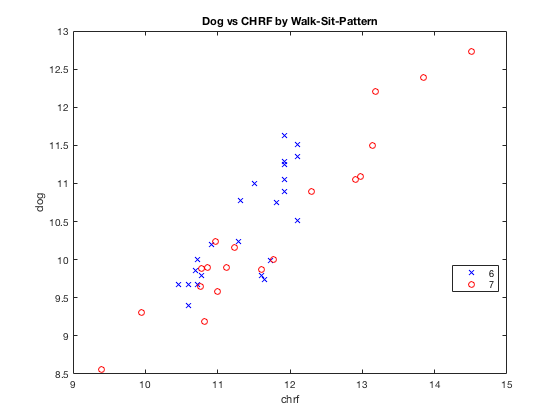

%STAT7164DOGGIE3.MLX

%   6000    980 71 
%1030000 240000 71 
%2000000 338000 71 %use 2.3m/2m+1 338000 similar result
%  50000   9800 71
%  60000  14500 71
% 110000  19300 71
%  48000  19650 71
% 510000  98600 71
% 430000  66000 71
% 400000  63000 71
% 218000  54000 71
%  52000  20000 71
%  76000  26000 71 

z=[ 
%7 701 2003  500000 350000 % -- Victoria Park Walk Pattern --
7 701 2004  530000 200000
7 701 2005   21000  11000
7 701 2006   58000  28000
7 701 2007   68000  20000
7 701 2008   47000  15500
7 701 2009   76000  26000
7 701 2010   52000  20000
7 701 2011  218000  54000
7 701 2012  400000  63000
7 701 2013  430000  66000
7 701 2014  510000  98600
7 701 2015   48000  19650
7 701 2016  110000  19300
7 701 2017   60000  14500
7 701 2018   50000   9800
7 331 2019   12000   5200  % 31.3 Extradiction Law
7 428 2019  130000  22000  % 28.4 Extradiction Law
7 609 2019 1030000 240000  % 9.6 Extradiction Law
7 616 2019 2000001 338000  % 16.6 Extradiction Law
6 604 1990  150000  80000  % -- Victoria Park Site Pattern --
6 604 1991  100000  60000
6 604 1992   80000  28000
6 604 1993   40000  12000
6 604 1994   40000  12000
6 604 1995   35000  16000
6 604 1996   45000  16000 % 1997 no police number 
6 604 1998   40000  16000
6 604 2004   82000  48000 % 1999-2003 no police number; 
6 604 2005   45000  22000
6 604 2006   44000  19000
6 604 2007   55000  27000
6 604 2008   48000  18000
6 604 2009  150000  62800
6 604 2010  150000 113000
6 604 2011  150000  77000
6 604 2012  180000  85000
6 604 2013  150000  54000 % no way the dog reported more, add one zero
6 604 2014  180000  99500
6 604 2015  135000  46600
6 604 2016  125000  21800
6 604 2017  110000  18000
6 604 2018  115000  17000
6 604 2019  180000  37000 
  ];

% see https://www.scmp.com/news/hong-kong/politics/article/3007194/proportion-regulars-annual-june-4-candlelight-vigil-hong

category = z(:,1);
mdd      = z(:,2);
year     = z(:,3);
chrf     = log(z(:,4));
dog      = log(z(:,5));

figure()
gscatter(chrf, dog, category, 'br', 'xo');
title('Dog vs CHRF by Walk-Sit-Pattern');



corr_table = table(dog, chrf, category);
corr_table.category = categorical(corr_table.category);


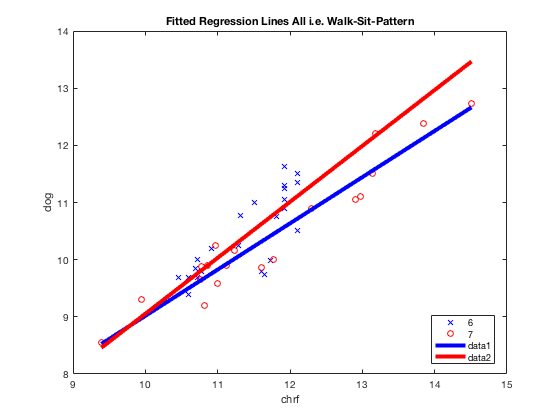

fit_all=fitlm(corr_table, 'dog~chrf*category');
myanova=anova(fit_all);

%err- plot(fit, dog, chrf);

cspace=linspace(min(chrf), max(chrf));

figure();
gscatter( chrf, dog, category, 'br', 'xo');
%line(cspace, feval(fit_all, cspace, '3'), 'Color', 'b', 'Linewidth', 4);
line(cspace, feval(fit_all, cspace, '7'), 'Color', 'b', 'Linewidth', 4);
line(cspace, feval(fit_all, cspace, '6'), 'Color', 'r', 'Linewidth', 4);
title('Fitted Regression Lines All i.e. Walk-Sit-Pattern');


% fit_all with category 

% R2
% 0.822 with    first protest
%               -0.73297+0.97867chrf+1.1841cat_7-0.1242cat_7*catgory

% 0.832 without first protest 
%               (make sense as the first protest caught
%                everyone by sureprise)
%                -0.73297+0.97867chrf+1.662cat_7-0.16983cat_7*catgory 


%%% but none of the intercept and the category/weigth are significant
%%% and also by itself 71 without the first protest is R2 .9

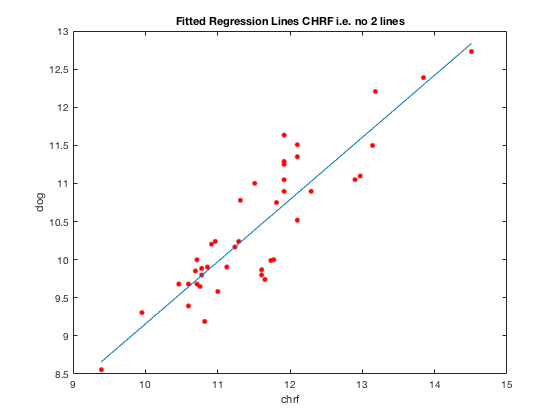

fit_chrf=fitlm(corr_table, 'dog~chrf');
myanova_chrf=anova(fit_chrf);

%err- plot(fit, dog, chrf);

cspace=linspace(min(chrf), max(chrf));
figure();
gscatter( chrf, dog);
%line(cspace, feval(fit_chrf, cspace, '3'), 'Color', 'b', 'Linewidth', 4);
%line(cspace, feval(fit_chrf, cspace, '7'), 'Color', 'b', 'Linewidth', 4);
line(cspace, feval(fit_chrf, cspace));
title('Fitted Regression Lines CHRF i.e. no 2 lines');


% fit_all with NO category 

% R2
% 0.805 with    first protest
%               0.59953+0.85239chrf

% 0.804 without first protest 
%               (NOT make sense; worst without the outlier?)
%                0.99555+0.81608chrf


# seems intercept and catgory is not useful

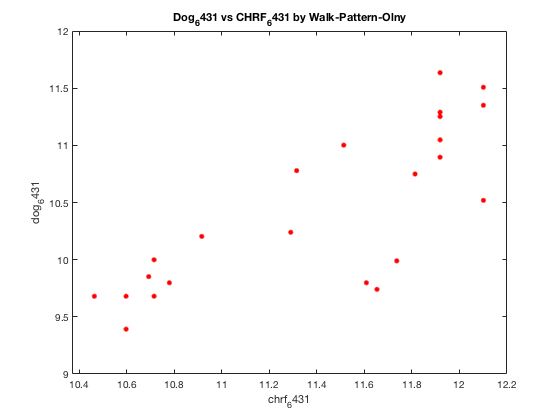

z_6431=[ 
6 604 1990  150000  80000  % -- Victoria Park Site Pattern --
6 604 1991  100000  60000
6 604 1992   80000  28000
6 604 1993   40000  12000
6 604 1994   40000  12000
6 604 1995   35000  16000
6 604 1996   45000  16000 % 1997 no police number 
6 604 1998   40000  16000
6 604 2004   82000  48000 % 1999-2003 no police number; 
6 604 2005   45000  22000
6 604 2006   44000  19000
6 604 2007   55000  27000
6 604 2008   48000  18000
6 604 2009  150000  62800
6 604 2010  150000 113000
6 604 2011  150000  77000
6 604 2012  180000  85000
6 604 2013  150000  54000 % no way the dog reported more, add one zero
6 604 2014  180000  99500
6 604 2015  135000  46600
6 604 2016  125000  21800
6 604 2017  110000  18000
6 604 2018  115000  17000
6 604 2019  180000  37000 
  ];

% see https://www.scmp.com/news/hong-kong/politics/article/3007194/proportion-regulars-annual-june-4-candlelight-vigil-hong

category_6431 = z_6431(:,1);
mdd_6431      = z_6431(:,2);
year_6431     = z_6431(:,3);
chrf_6431     = log(z_6431(:,4));
dog_6431      = log(z_6431(:,5));

figure()
gscatter(chrf_6431, dog_6431);
title('Dog_6431 vs CHRF_6431 by Walk-Pattern-Olny');

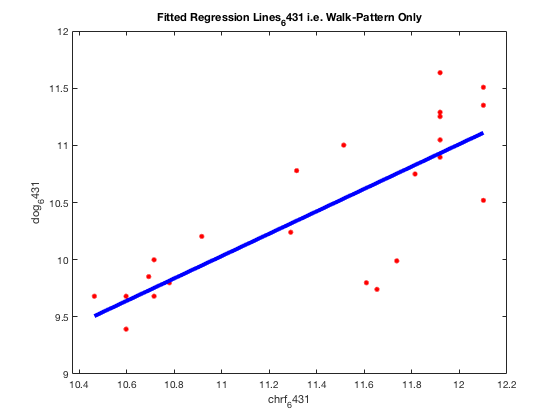


corr_table_6431 = table(dog_6431, chrf_6431, category_6431);
corr_table_6431.category_6431 = categorical(corr_table_6431.category_6431);

fit_6431=fitlm(corr_table_6431, 'dog_6431~chrf_6431');
myanova=anova(fit_6431);

% fit_6431

% R2
% 0.891 with    first protest
%               -0.73297+0.97867chrf

%err- plot(fit, dog, chrf);

cspace_6431=linspace(min(chrf_6431), max(chrf_6431));

figure();
gscatter( chrf_6431, dog_6431);
%line(cspace, feval(fit_all, cspace, '3'), 'Color', 'b', 'Linewidth', 4);
line(cspace_6431, feval(fit_6431, cspace_6431), 'Color', 'b', 'Linewidth', 4);
title('Fitted Regression Lines_6431 i.e. Walk-Pattern Only');

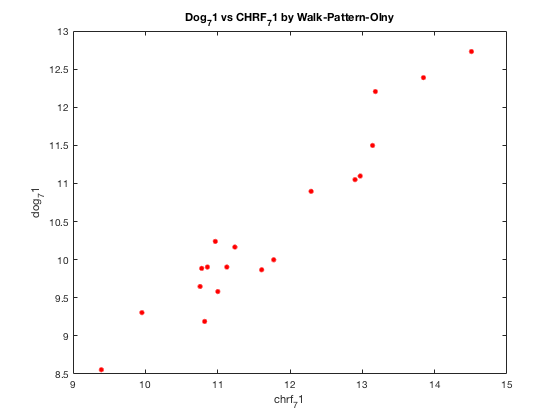

z_71=[ 
%7 701 2003  500000 350000 % -- Victoria Park Walk Pattern --
7 701 2004  530000 200000
7 701 2005   21000  11000
7 701 2006   58000  28000
7 701 2007   68000  20000
7 701 2008   47000  15500
7 701 2009   76000  26000
7 701 2010   52000  20000
7 701 2011  218000  54000
7 701 2012  400000  63000
7 701 2013  430000  66000
7 701 2014  510000  98600
7 701 2015   48000  19650
7 701 2016  110000  19300
7 701 2017   60000  14500
7 701 2018   50000   9800
7 331 2019   12000   5200  % 31.3 Extradiction Law
7 428 2019  130000  22000  % 28.4 Extradiction Law
7 609 2019 1030000 240000  % 9.6 Extradiction Law
7 616 2019 2000001 338000  % 16.6 Extradiction Law

  ];

% see https://www.scmp.com/news/hong-kong/politics/article/3007194/proportion-regulars-annual-june-4-candlelight-vigil-hong

category_71 = z_71(:,1);
mdd_71      = z_71(:,2);
year_71     = z_71(:,3);
chrf_71     = log(z_71(:,4));
dog_71      = log(z_71(:,5));

figure()
gscatter(chrf_71, dog_71);
title('Dog_71 vs CHRF_71 by Walk-Pattern-Olny');

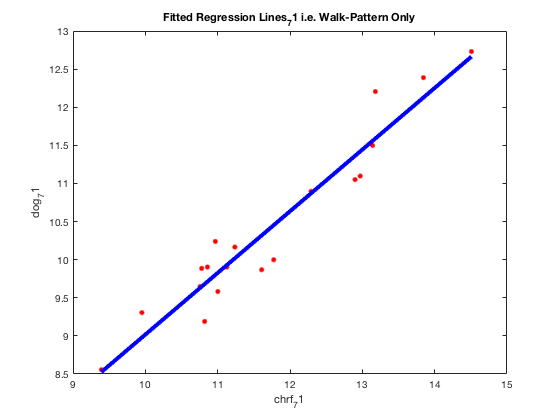


corr_table_71 = table(dog_71, chrf_71, category_71);
corr_table_71.category_71 = categorical(corr_table_71.category_71);

fit_71=fitlm(corr_table_71, 'dog_71~chrf_71');
myanova=anova(fit_71);

% fit_71

% R2
% 0.891 with    first protest
%               0.45111+0.85446

% 0.924 without first protest 
%               (make sense as the first protest caught
%                everyone by sureprise)
%                0.92899+0.80883


%err- plot(fit, dog, chrf);

cspace_71=linspace(min(chrf_71), max(chrf_71));

figure();
gscatter( chrf_71, dog_71);
%line(cspace, feval(fit_all, cspace, '3'), 'Color', 'b', 'Linewidth', 4);
line(cspace_71, feval(fit_71, cspace_71), 'Color', 'b', 'Linewidth', 4);
title('Fitted Regression Lines_71 i.e. Walk-Pattern Only');

%anova(fit_all);

%%myfittype = fittype (‘c+m*x’, ‘dependent’, ‘y’);
%%myfit = fit(x, y, myfittype)
%myfit = fitlm(x, y)
%%plot(myfit, x, y)
%plot(myfit)
%xlabel(‘log CHRF’)
%ylabel(‘log dog’)

%scatter(z(:,1)/1000, z(:,2)/1000)
%xlim([0,1000])
%ylim([0,1000])

